% a) Defining Variables and Performing Simple Operations
a = 5;
b = 3;
multiplication = a * b

multiplication = 15

addition = a + b

addition = 8

division = a / b

division = 1.6667

subtraction = a - b

subtraction = 2


% b) Clearing the Workspace and Command Window
clear
clc

% Redefining variables after clear
a = 5;
b = 3;

% c) Defining Arrays and Performing the Transpose Operation
c = [1, 2, 3];            % 1D array
d = [1, 2; 3, 4];         % 2D array
d_transpose = d'          % Transpose of matrix d

d_transpose =      1     3
     2     4



% d) Matrix Multiplication
A = [1, 2; 3, 4];
B = [5, 6; 7, 8];
elementwise = A .* B      % Element-wise multiplication

elementwise =      5    12
    21    32


matrix_product = A * B    % Matrix multiplication

matrix_product =     19    22
    43    50



% e) Defining Custom Functions
f = @(x) x.^2 + 3*x + 2;
f_val = f([1, 2, 3])       % Apply function to array

f_val =      6    12    20



g = @(x, y) x.^2 + y.^2;
g_val = g(1, 2)            % Apply function to scalars

g_val = 5


% f) Adding Comments
% Comments are already added using '%' before each explanation

## Q2: Pre-defined MATLAB Functions and Visualization

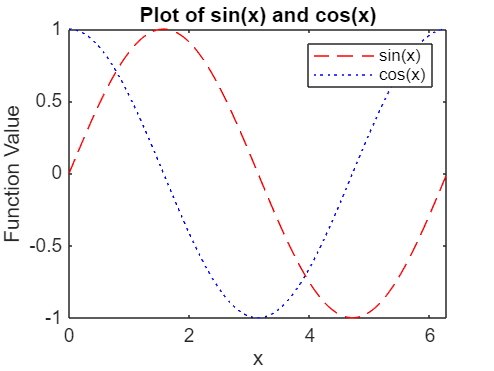

% a) Linear Spaces and Evaluating Functions
x = linspace(0, 2*pi, 100);
y_exp = exp(x);
y_sin = sin(x);

% b) Plotting Single Variable Functions
figure;
plot(x, sin(x), 'r--', 'DisplayName', 'sin(x)'); hold on;
plot(x, cos(x), 'b:', 'DisplayName', 'cos(x)');
legend;
xlabel('x');
ylabel('Function Value');
title('Plot of sin(x) and cos(x)');

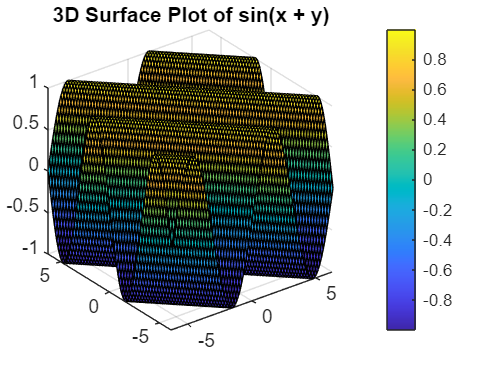


% c) Using Meshgrid to Generate 2D Spaces
x2 = linspace(-2*pi, 2*pi, 100);
y2 = linspace(-2*pi, 2*pi, 100);
[X, Y] = meshgrid(x2, y2);
Z = sin(X + Y);

% d) Visualizing Multivariable Functions

% Surface plot
figure;
surf(X, Y, Z);
colorbar;
title('3D Surface Plot of sin(x + y)');

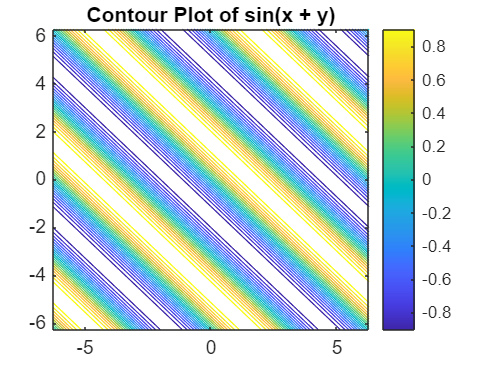


% Contour plot
figure;
contour(X, Y, Z, 20);
colorbar;
title('Contour Plot of sin(x + y)');

## Q3: Loops, Integration, and Vectorization

% a) Introduction to Loops
val = 0;
for i = 1:10
    val = val + 1;
end
val

val = 10


% b) Numerical Integration using Riemann Sums
a = 0; b = 2*pi; n = 1000;
dx = (b - a) / n;
sum_riemann = 0;
for i = 0:n-1
    x_riem = a + i * dx;
    sum_riemann = sum_riemann + sin(x_riem) * dx;
end
sum_riemann

sum_riemann = 2.8313e-16


% c) Vectorized Riemann Sum with Linspace
x_mid = linspace(a + 0.5*dx, b - 0.5*dx, n);
tic;
y = sin(x_mid);
area_vectorized = sum(y) * dx;
toc;

Elapsed time is 0.007181 seconds.


area_vectorized

area_vectorized = -7.0853e-17


% d) Built-in Integration Function
integral_result = integral(@sin, 0, 2*pi);
integral_result

integral_result = -5.5511e-17